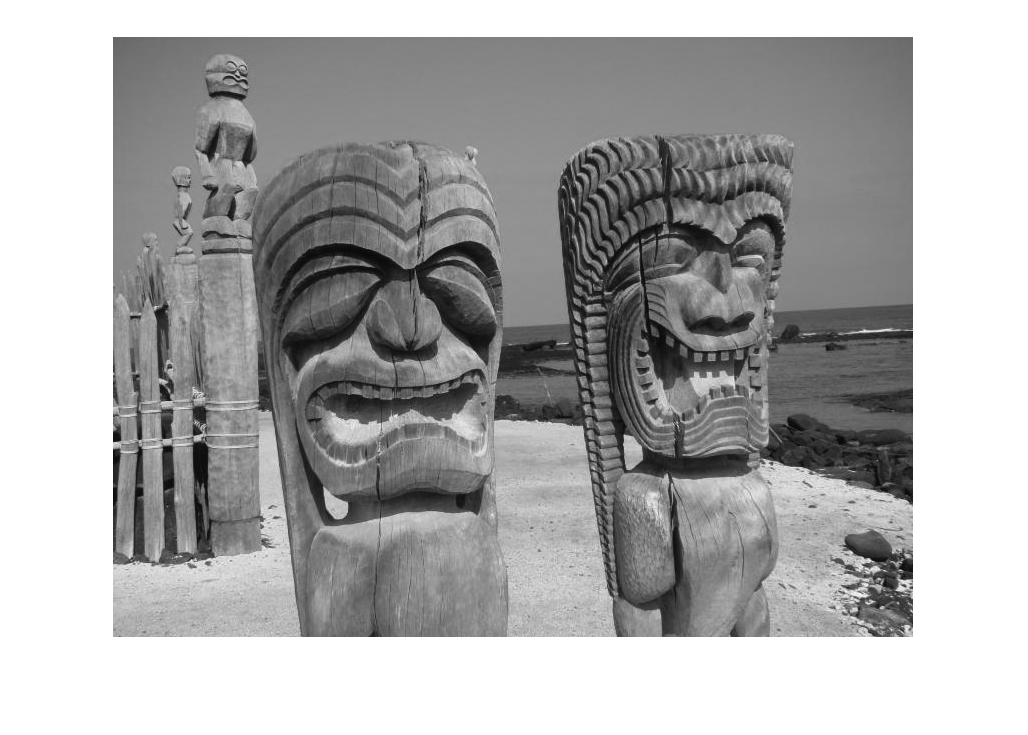

oldImage = im2double(imread("totem-poles.tif"));
imshow(oldImage)


[m,n] = size(oldImage) % get size of image

m = 600

n = 800


scalar = .5; % pick a scalar

newImage = zeros(round((size(oldImage) * scalar)));
[newM,newN] = size(newImage)

newM = 300

newN = 400

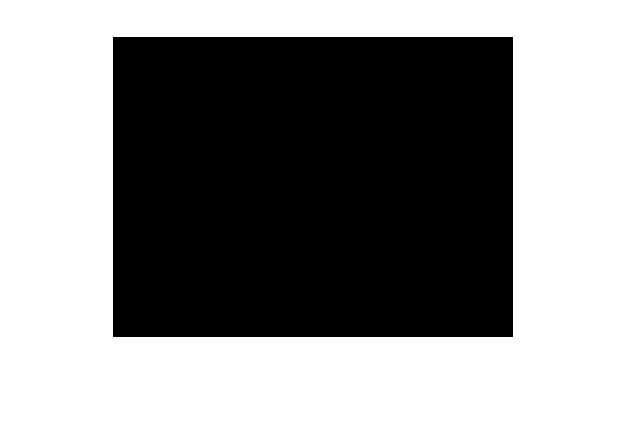

imshow(newImage)


IntermImage = zeros([m,newN]);
size(IntermImage)

ans =    600   400


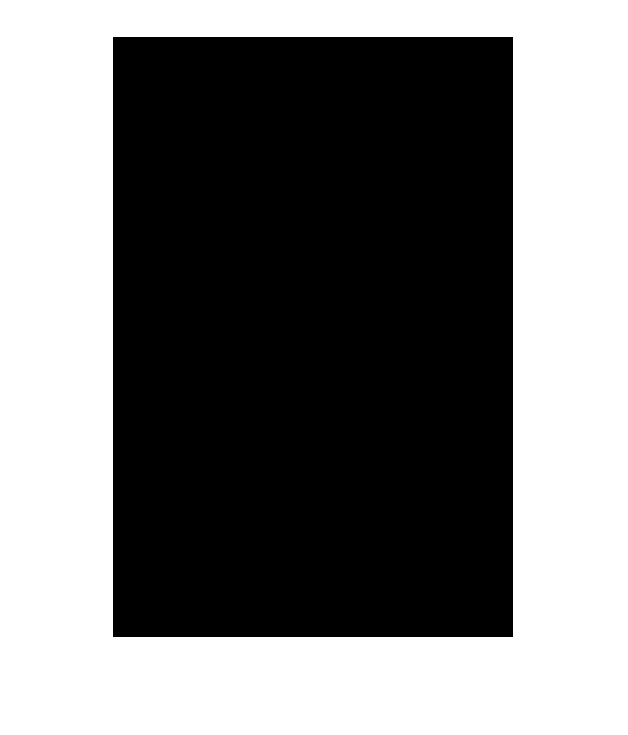

imshow(IntermImage)

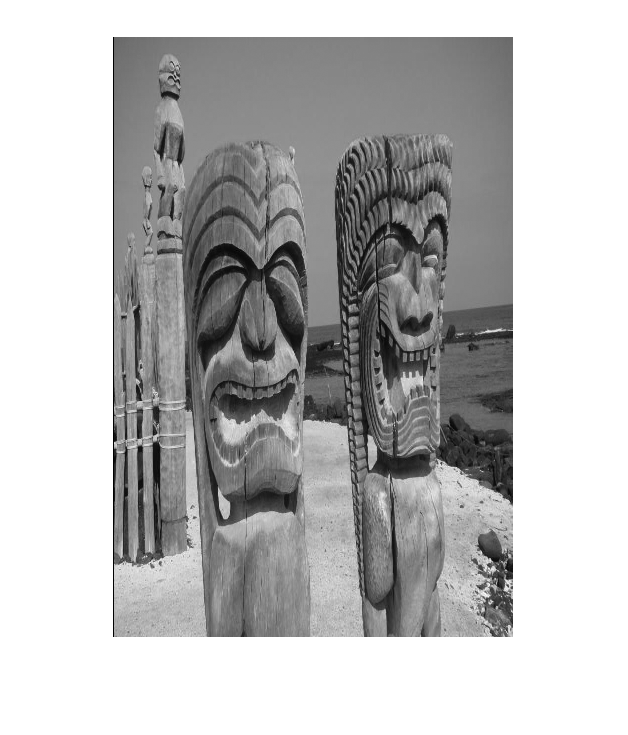


oldImageGap = n - 1; % Gets number of spaces between pixesl of old Image 
newImageGap = newN - 1; % Gets number of spaces between pixesl of new Image    

factor = lcm(oldImageGap, newImageGap); % gets least common multiple of image spaces 

% divisionsOld = factor / oldImageGap; % find number of divisions between pixesl in old image
% divisionsNew = factor / newImageGap; % find number of division between pixels in new image
%         
% subDivisionsOld = 1 / divisionsOld; % gets sub divisions between old image pixel values
% subDivisionsNew = 1 / divisionsNew; % gets sub divisions between new image pixel values 

ticks_oldImage = 1; % start tick counter for old image
ticks_newImage = 1; % start tick counter for new image

for i = newN : factor 
    
    amountOfPixel_oldImage = ticks_oldImage / oldImageGap; % gets fraction of a pixel in old image
    amountOfPixel_newImage = ticks_newImage / newImageGap; % gets fraction of a pixel in new image
   
    ticks_oldImage = ticks_oldImage + 1; % increment tick position of old image
    ticks_newImage = ticks_newImage + 1; % increment tick position of new image
    
    if amountOfPixel_oldImage == 1
        amountOfPixel_oldImage = 0;
        ticks_oldImage = 1;  
    end
    
    if amountOfPixel_newImage == 1
        amountOfPixel_newImage = 0;
        ticks_newImage = 1;
    end
    
    pixelRowIndex_oldImage = round(i / newImageGap) + 1; % this will get me the index of the pixel my old image
    pixelRow_Index_newImage = round(i / oldImageGap) + 1; % this will get me the index of the pixel my new image
    
    
    for r = 1 : m
        IntermImage(r, pixelRow_Index_newImage) = ...
        (1 - amountOfPixel_oldImage)*oldImage(r, pixelRowIndex_oldImage) ...
        + amountOfPixel_oldImage * oldImage(r, pixelRowIndex_oldImage);          
    end
   
end

imshow(IntermImage)